# Getting Started with parfeval 

In this exercise, we will use parfeval with a data queue to send data from the workers to the MATLAB client.

doc parfeval
doc fetchNext

## Give the quiz

In this problem, we are giving a quiz to 20 students, monitored by proctors (workers).  Each student will finish in a random period of time (max 5 minutes) and we expect each student will get some random grade (between 49 and 100).

The for-loop will gather all the timings to be plotted in a stem plot at the completion of the quiz, but MATLAB should also be listening to "events" (when the grades get posted) via a dataqueue.  The grades will be written to a "database" (the MATLAB Command Window in this case) in real-time.

As the grades come back, if a certain number fail, the quiz will stop prematurely to avoid wasting the time of the proctors.

% Create a data queue so workers can send the grades back to the client once
% they're done
%
% DONE: Create a dataqueue object.  Assign it to 'q'.
q = parallel.pool.DataQueue;


% After each quiz is taken, log the grade
%
% DONE: Call afterEach() with the dataqueue (q) and a pointer to the
% function (@lPostGrade)
afterEach(q,@lPostGrade)


nStudents = 20;
lowgrade = 49;
highgrade = 100;
timings = nan(nStudents,1);

for sidx = 1:nStudents
    % TODO: Schedule a quiz (lGiveQuiz) with a proctor.  lGiveQuiz
    % will return two outputs arguments.  It is passed an expected
    % grade range (as [min max]) and the dataqueue to send the grade
    % back the MATLAB client.
    quizzes(sidx) = parfeval(@lGiveQuiz,2,[lowgrade highgrade],q);
end

nFailed = 0;
TOO_MANY = 2;
for sidx = 1:nStudents
    % TODO: Fetch the quizzes as they are completed.  lGiveQuiz will return
    % the time it took (timings) to take the quiz and whether the student
    % failed or not (failed).
    %
    % NOTE: Outputs from lGiveQuiz
    %   timings: 1 x nStudents double
    %   failed:  1 x 1 boolean
    
    % ... Enter code here to fetch the next quiz result...
    [idx,timings,failed] = fetchNext(quizzes)

    if failed
        nFailed = nFailed+1;
        if nFailed>TOO_MANY
            fprintf("Too many failed grades.  Terminating quiz.\n")
            % TODO: Too many quizzes have failed.  Cancel the remaining
            % quizzes.

            % ... Enter the code here to cancel the remaining quizzes ...
            quizzes.cancel

            % Extra Credit:  Do need to "break" out of the for-loop?  What
            % happens if we don't?
            break
        end
    end
end

idx = 1

timings = 3.1387

failed = logical
   0


idx = 2

timings = 2.6831

failed = logical
   1


idx = 4

timings = 1.5097

failed = logical
   0


idx = 3

timings = 2.2629

failed = logical
   0


idx = 8

timings = 1.0615

failed = logical
   1


idx = 6

timings = 2.7030

failed = logical
   1


idx = 5

timings = 2.8100

failed = logical
   0


idx = 11

timings = 0.2072

failed = logical
   1


idx = 12

timings = 1.5224

failed = logical
   1


idx = 10

timings = 1.9547

failed = logical
   0


idx = 7

timings = 4.8817

failed = logical
   0


idx = 9

timings = 3.4688

failed = logical
   0


idx = 15

timings = 1.2625

failed = logical
   1


idx = 14

timings = 3.5395

failed = logical
   0


idx = 13

timings = 3.9830

failed = logical
   0


idx = 18

timings = 0.3857

failed = logical
   0


idx = 19

timings = 0.3189

failed = logical
   0


idx = 20

timings = 0.3621

failed = logical
   1


idx = 16

timings = 4.0768

failed = logical
   0


idx = 17

timings = 4.6213

failed = logical
   1



fprintf("Quiz is complete.\n")

Quiz is complete.


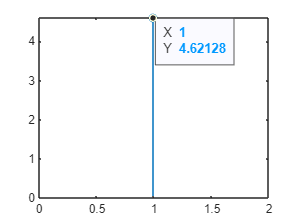


% Chart the timings
lChartTimings(timings)

#### Helper functions

function [quiztime, failed] = lGiveQuiz(graderange,q)
% GRADERANGE is a 1x2 vector [low high] range of grades
% Q is a handle to a parallel DataQueue

% Each student takes a random amount of time to take the quiz
% (up to 5 "minutes")
quiztime = 5 * rand;
pause(quiztime)

% Generate a uniformly distributed pseudorandom score in the grade range
% (e.g., 49 to 100)
grade = randi(graderange);
failed = grade<70;

% Send the timing back to record the timing while the remaining students
% finish their work
% DONE: Call send() to pass the grade (grade) of the quiz back to the
% MATLAB client
send(q,grade)

end

function lPostGrade(grade)

fprintf("Grade: %d\n", grade)

end

function lChartTimings(timings)
% Create stem plot of timings

h = stem(timings,"filled");
axis tight

% Display data tips to show timings
datatip(h);

end

% Turn off Code Analyzer warnings
%#ok<*DEFNU>
%#ok<*INUSD>
%#ok<*SAGROW>

*Copyright 2024 The MathWorks, Inc.*